# Effects of high migration on density distribution - SSM

Calculate the distribution of individuals in demes in a stepping stone model. $N_1$ is the population in the lastly deteriorated deme, $N_2$ the deme at its left, $N_3$ to its left, and so on. We assume $mN_4\ll1$. At equilibrium and ignoring dynamics related to $r$:

syms N1 N2 N3 kappa m r
eqn1 = N1==N1*(1-m-r)+m/2*kappa+m/2*N2

$$eqn1 = N_{1}=\frac{N_{2}\,m}{2}+\frac{\kappa \,m}{2}-N_{1}\,\left(m+r-1\right)$$

eqn2 = N2==N2*(1-m-r)+m/2*N1+m/2*N3

$$eqn2 = N_{2}=\frac{N_{1}\,m}{2}+\frac{N_{3}\,m}{2}-N_{2}\,\left(m+r-1\right)$$

eqn3 = N3==N3*(1-m-r)+m/2*N2

$$eqn3 = N_{3}=\frac{N_{2}\,m}{2}-N_{3}\,\left(m+r-1\right)$$


N3 = solve(eqn3, N3)

$$N3 = \frac{N_{2}\,m}{2\,\left(m+r\right)}$$

eqn2 = N2==N2*(1-m-r)+m/2*N1+m/2*N3

$$eqn2 = N_{2}=\frac{N_{1}\,m}{2}-N_{2}\,\left(m+r-1\right)+\frac{N_{2}\,m^{2}}{4\,\left(m+r\right)}$$

N2 =solve(eqn2, N2)

$$N2 = \frac{N_{1}\,m}{2\,\left(m+r-\frac{m^{2}}{4\,\left(m+r\right)}\right)}$$

eqn1 = N1==N1*(1-m-r)+m/2*kappa+m/2*N2

$$eqn1 = N_{1}=\frac{\kappa \,m}{2}-N_{1}\,\left(m+r-1\right)+\frac{N_{1}\,m^{2}}{4\,\left(m+r-\frac{m^{2}}{4\,\left(m+r\right)}\right)}$$

N1 = solve(eqn1, N1)

$$N1 = \frac{\kappa \,m}{2\,\left(m+r-\frac{m^{2}}{4\,\left(m+r-\frac{m^{2}}{4\,\left(m+r\right)}\right)}\right)}$$

OK now we have a self contained form for $N_1$ and we can plot it as a function of $m$:

N1plot = subs(subs(N1, r=0.5), kappa=200)

$$N1plot = \frac{100\,m}{m-\frac{m^{2}}{4\,\left(m-\frac{m^{2}}{4\,\left(m+\frac{1}{2}\right)}+\frac{1}{2}\right)}+\frac{1}{2}}$$

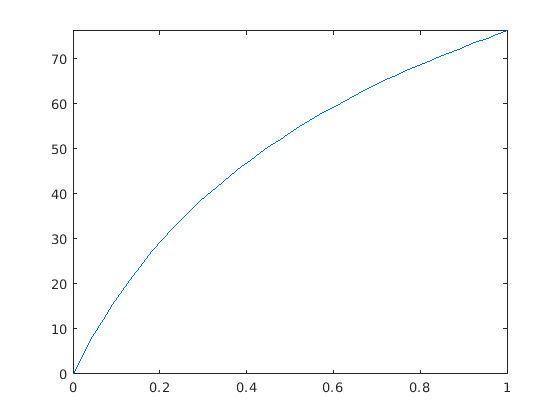

fplot(N1plot, [0 1])